In `PDEs.mlx`, we talk about the heat equation in a rod, which models the temperature distribution at all positions $x$ in the rod at any given time $t$.

It turns out that if you wait long enough, the temperature distribution will reach an equilibrium state that can be modeled with a simpler differential equation. Instead of a PDE involving both $x$ and $t$, this simpler ODE only involves $x$.

In boring cases, the temperature will just spread out until it's equal everywhere. But if there are special boundary conditions placed on the rod—such as making each end have a constant temperature by putting it in ice or fire—the equilibrium temperature distribution gets more interesting.

If surrounded by an ambient temperature $T_a$, the temperature $T_1(x)$ of a position $x$ in a rod **at equilibrium** can be modeled by this 2nd-order ODE:

        $\frac{d^2T_1}{dx^2} = -k(T_a - T_1)$ with boundary conditions $\begin{cases} T_1(0, t) = T_0\\ T_1(L, t) = T_L\end{cases}$ at any time $t$ (although $t$ plays no role in this ODE).

In that equation, $k$ is a coefficient defined by $k = \frac{2h}{r\kappa}$ [in units of m$^{-2}$].

        $h$: the rod's convection heat transfer coefficient [J/(m$^2$•K•s), or equivalently, W/(m$^2$•K)]

        $r$: the rod's radius [m]

        $\kappa$: the rod's thermal conductivity [J/(s•m•K), or equivalently, W/(m•K)]

**In the slides and homework, k is called "thermal conductivity" instead of **$\kappa$**! I think it's a misprint. When working on the homework, go along with that; ignore the equation I just gave for k.**

L = 1;      % Length of rod
x = linspace(0, L, 100); % Positions in the rod

T_a = 25;   % Ambient temperature
k = 0.1;    % Thermal conductivity

T_0 = 100;  % Temperature at the beginning of the rod (x = 0)
T_L = 70;   % Temperature at the end of the rod (x = L for some L)

## Coding the ODE

If we define a new symbol $T_2$ as $T_2 = \frac{dT_1}{dx}$, then $\frac{dT_2}{dx} = \frac{d^2 T_1}{dx^2} = -k(T_a - T_1)$.

So the 2nd-order ODE can be rewritten as this system of 1st-order ODEs: $\begin{cases} \frac{dT_1}{dx} = T_2 \\ \frac{dT_2}{dx} = -k(T_a - T_1) \end{cases}$ .

This can also be written as $\left\lbrack \begin{array}{c}
\frac{{\textrm{dT}}_1 }{\textrm{dx}}\\
\frac{{\textrm{dT}}_2 }{\textrm{dx}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
T_2 \\
-k\left(T_a -T_1 \right)
\end{array}\right\rbrack$, the derivative ($T'$, or `Tp` in the code) of a vector $T=\left\lbrack \begin{array}{c}
T_1 \\
T_2 
\end{array}\right\rbrack$.

Tp = @(x,T) [T(2); -k*(T_a - T(1))];  % x isn't used

## Coding the boundary conditions

I'll write the boundary conditions $\begin{cases} T_1(0, t) = T_0\\ T_1(L, t) = T_L\end{cases}$ as $\begin{cases} T_1(0) = T_0\\ T_1(L) = T_L\end{cases}$ from now on, since $t$ was really only there for conceptual understanding and isn't important otherwise.

So we already know that $T_1(0) = T_0$ and $T_1(L) = T_L$, but `bvp4c` doesn't. The way to tell it those values is awkward: we give it a vector$\left\lbrack \begin{array}{c}
T_1 \left(0\right)-T_0 \\
T_1 \left(L\right)-T_L 
\end{array}\right\rbrack$, which it will set equal to $\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$ to figure out that $\begin{cases} T_1(0) = T_0\\ T_1(L) = T_L\end{cases}$.

In the code, `ya(1)` will represent $T_1 \left(0\right)$, the first component of `ya` = $T\left(0\right)$; and `yb(1)` will represent $T_1 \left(L\right)$, the first component of `yb` = $T\left(L\right)$. (These are $T\left(x\right)=\left\lbrack \begin{array}{c}
T_1 \left(x\right)\\
T_2 \left(x\right)
\end{array}\right\rbrack$ evaluated at $x=0$ or $x=L$.)

To let `bvp4c` make guesses(?) at what `ya` and `yb` are, we have to define $\left\lbrack \begin{array}{c}
T_1 \left(0\right)-T_0 \\
T_1 \left(L\right)-T_L 
\end{array}\right\rbrack$ as a MATLAB function `bc`, which will be given to `bvp4c` later:

bc = @(ya, yb) [ya(1) - T_0; yb(1) - T_L];    % Each component is set equal to zero

## Coding the initial guess

`bvp4c` needs us to make an initial guess of what the temperature distribution $T(x)$ might look like.

Here, we'll guess that $T\left(x\right)=\left\lbrack \begin{array}{c}
T_1 \left(x\right)\\
T_2 \left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
T_L 
\end{array}\right\rbrack$. Since $T_2(x)$ was originally defined as $\frac{dT_1}{dx}$, this guess means "the temperature is 0 everywhere, yet its rate of change along $x$ is $T_L$." A little contradictory, but somehow does the trick!

init = bvpinit(x, [0,T_L]);

## The solution

Here it is:

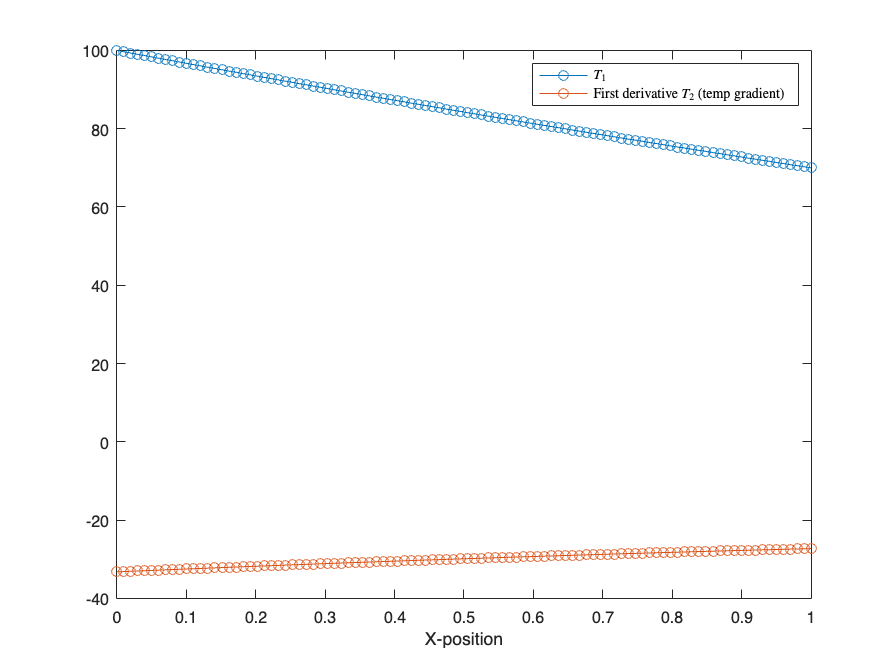

sol = bvp4c(Tp, bc, init);

figure;
plot(sol.x, sol.y, '-o')
xlabel('X-position');
% legend('Second derivative', 'First derivative (temp gradient)');
legend('$T_1$', 'First derivative $T_2$ (temp gradient)', 'interpreter', 'latex');